# Homework 10 (Solutions)

Math 3607, Spring 2022

Tae Eun Kim

clear, close all, format short 

## Problem 1 (Secant method)

Omitted.

## Problem 2 (Multidimensional Newton's method; FNC 4.5.5)

(a) Moving all terms to one side and simplifying, we have


$$\begin{array}{rcl}
  \left(1 - \frac{\lambda}{25}\right) x - 5 & = & 0 \\
  \left(1 - \frac{\lambda}{16}\right) y - 4 & = & 0 \\
  \left(1 - \frac{\lambda}{9}\right) z - 3 & = & 0 \\
  \frac{1}{25} x^2 + \frac{1}{16}y^2 + \frac{1}{9}z^2 - 1 & = & 0
\end{array}$$


This is good enough. But for the last part, it is advantageous to write in the form $\mathbf{f}(\mathbf{u}) = \mathbf{0}$ as suggested by the problem. Let $\mathbf{u} = (u_1, u_2, u_3, u_4)^{\rm T} = (x, y, z, \lambda)^{\rm T}$, the vector consisting of all four unknowns. Then, abstractly, we may view/write the system of these four equations as a single vector equation $\mathbf{f}(\mathbf{u}) = \mathbf{0}$,  


$$
\[
  \mathbf{f}(\mathbf{u}) =
  \left[ \; \matrix{
      f_1(u_1, u_2, u_3, u_4) \cr
      f_2(u_1, u_2, u_3, u_4) \cr
      f_3(u_1, u_2, u_3, u_4) \cr
      f_4(u_1, u_2, u_3, u_4)
    }\; \right]
  =
  \left[ \; \matrix{
      (1-u_4/25) u_1 - 5 \cr
      (1-u_4/16) u_2 - 4\cr
      (1-u_4/9) u_3 - 3\cr
      u_1^2/25 + u_2^2/16 + u_3^2/9 - 1
    }\; \right]  
\]$$


simply by replacing $x, y, z, \lambda$ by $u_1, u_2, u_3, u_4$, respectively. 

(b) In terms of the original variables $x,y,z,\lambda$, we can express the Jacobian matrix as


$$\[
  \mathbf{J}(x,y,z,\lambda) =
  \left[ \; \matrix{
      1-\lambda/25 & 0 & 0 & -x/25 \cr
      0 & 1-\lambda/16 & 0 & -y/16 \cr
      0 & 0 & 1-\lambda/9 & -z/9 \cr
      2x/25 & 2y/16 & 2z/9 & 0
    }\; \right]
\]
$$


which can be rewritten in terms of $\mathbf{u} = (u_1, u_2, u_3, u_4)^{\rm T} =  (x,y,z,\lambda)^{\rm T}$ as

$
\[
  \mathbf{J}(\mathbf{u}) =
  \left[ \; \matrix{
      1-u_4/25 & 0 & 0 & -u_1/25 \cr
      0 & 1-u_4/16 & 0 & -u_2/16 \cr
      0 & 0 & 1-u_4/9 & -u_3/9 \cr
      2u_1/25 & 2u_2/16 & 2u_3/9 & 0
    }\; \right]
\]
$.

The latter will be useful in the next part.

(c) In order to use `newtonsys` to find roots of $\mathbf{f}$, we first need to write a function m-file calculating both $\mathbf{f}$ and $\mathbf{J}$. Inspired by the example in the live script accompanying Lecture 32, we write

(This function is included at the end of this live script.)

Then we are able to use `newtonsys` as follows.

format short
x1 = newtonsys(@nlsystem, [1 1 1 1])

x1 =     1.0000    4.6945    3.5843    3.4311    3.4241    3.4241    3.4241
    1.0000    3.4446    2.4818    2.3311    2.3268    2.3268    2.3268
    1.0000    1.8336    1.4283    1.3186    1.3167    1.3167    1.3167
    1.0000  -11.3310  -10.2192  -11.3800  -11.5053  -11.5056  -11.5056


Note that the name of the function must be passed with at-sign in its front since it is defined as an m-file. (If you defined a function in-line as an anonymous function, the at-sign is unnecessary.)

To find another solution, use a different initial guess. 

x2 = newtonsys(@nlsystem, [-1 -1 -1 1])

x2 =    -1.0000    2.1306   -0.8437  -11.7432   -6.6115   -4.7672   -4.4169   -4.4038   -4.4037   -4.4037
   -1.0000   -0.6577   -1.5221   -3.5260   -2.5298   -1.8132   -1.7221   -1.7119   -1.7119   -1.7119
   -1.0000   -5.8583   -3.8719   -1.5987   -0.7062   -0.6950   -0.6045   -0.6084   -0.6083   -0.6083
    1.0000   74.8662   35.9427   31.7917   38.6124   47.7038   52.8890   53.3832   53.3850   53.3850


**Check.** Are the solutions really on the ellipsoid?

eq_ellips = @(u) u(1)^2/25 + u(2)^2/16 + u(3)^2/9 - 1;
p1 = x1(1:3,end);
p2 = x2(1:3,end);
format short e
[eq_ellips(p1), eq_ellips(p2)]'

ans =      0
     0


Yes, they are!

**Closest or Farthest?**

One of the two solutions have all positive components while the other has all negative components. The former should be closest while the latter farthest, because the given point $(5,4,3)$ lies in the first octant. 

Run the following script and rotate the generated 3-D figure around to stop the closest and the farthest points. 

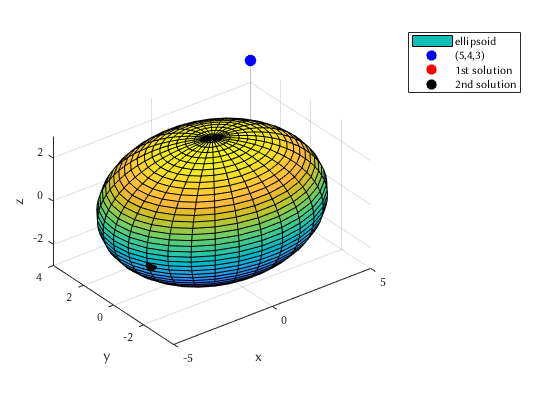

nr_th = 31;
nr_ph = 41;
th = linspace(0, 2*pi, nr_th);
ph = linspace(0, pi, nr_ph);
[TH,PH] = meshgrid(th, ph);
a = 5; b = 4; c = 3;
x = a*sin(PH).*cos(TH);
y = b*sin(PH).*sin(TH);
z = c*cos(PH);
clf
surf(x,y,z), hold on, axis equal
xlabel('x'), ylabel('y'), zlabel('z')
plot3(5,4,3, 'b.', 'MarkerSize', 30)
plot3(p1(1), p1(2), p1(3), 'r.', 'MarkerSize', 30)
plot3(p2(1), p2(2), p2(3), 'k.', 'MarkerSize', 30)
legend('ellipsoid', '(5,4,3)', '1st solution', '2nd solution')

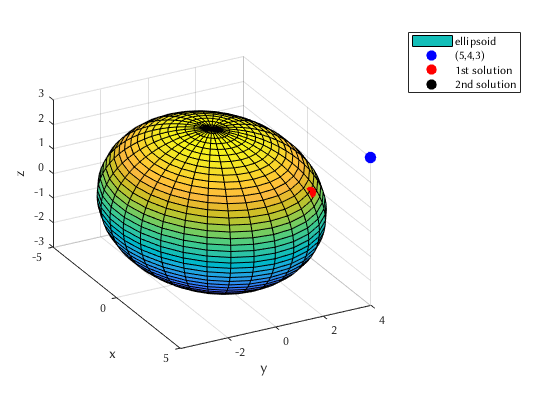

view([62 25])   % better viewing angle for the first solution

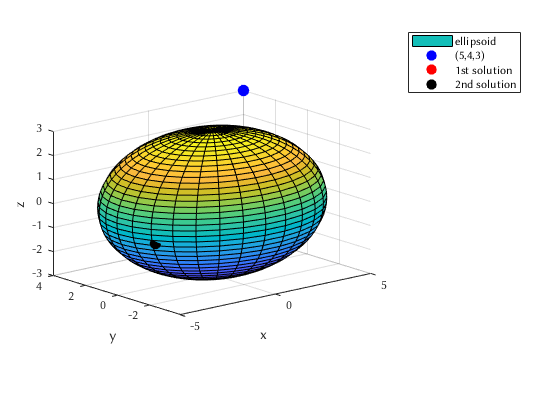

view([-40 15])  % better viewing angle for the second solution

## Problem 3 (Interpolating population; FNC 5.1.2)

(a,b)

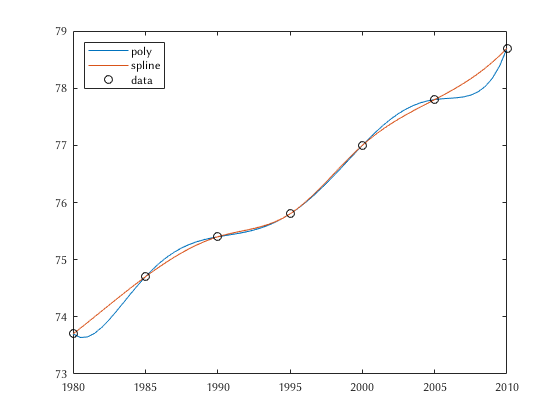

tdp = [1980:5:2010] - 1980;                    % abscissas: year since 1980
ydp = [73.7 74.7 75.4 75.8 77.0 77.8 78.7];    % ordinates: expectancy
n = length(tdp);
t = linspace(1980, 2010, 61)-1980;             % all half-years since 1980
ypoly = polyval(polyfit(tdp,ydp,n-1), t);
yspl = interp1(tdp, ydp, t, 'spline');
clf
plot(t+1980, ypoly), hold on
plot(t+1980, yspl)
plot(tdp+1980, ydp, 'ko')
legend('poly', 'spline', 'data', 'Location', "Northwest")

(c) By how `t` was constructed, the 6th from the last element correspond to year 2007.

1980+t(end-6)

ans =         2007

So the estimate expectancy for a person born in 2007 was already computed and stored:

ypoly(end-6)

ans =    7.7847e+01

yspl(end-6)

ans =    7.8084e+01

Based on the graph abvoe, the result by spline (78.084) appears to be more believeable. 

**Note.** You can find a single estimate directly by using `polyfit` or `interp1` as well:

targetYear = 2007;
polyval(polyfit(tdp,ydp,n-1), targetYear-1980)

ans =    7.7847e+01

interp1(tdp, ydp, targetYear-1980, "spline")

ans =    7.8084e+01

## Problem 4 (Piecewise cubic interpolation; FNC 5.1.3)

One may directly type in the given coordinates. In real applications, such information may be stored in data files, *e.g.,*

and

If these files are saved in the same directory as your main live script, you can import the data using `load` function

load('shape_top.dat')
load('shape_bottom.dat')

The data files are now loaded and  are stored as `shape_top` and `shape_bottom:`

shape_top

shape_top =             0            0
   5.1000e-01   1.6000e-01
   9.6000e-01   1.6000e-01
   1.0600e+00   4.3000e-01
   1.2900e+00   6.2000e-01
   1.5500e+00   4.8000e-01
   1.7300e+00   1.9000e-01
   2.1300e+00   1.8000e-01
   2.6100e+00            0


shape_bottom

shape_bottom =             0            0
   5.8000e-01  -1.6000e-01
   1.0400e+00  -1.5000e-01
   1.2500e+00  -3.0000e-01
   1.5600e+00  -2.9000e-01
   1.7600e+00  -1.2000e-01
   2.1900e+00  -1.2000e-01
   2.6100e+00            0


### Version 1.

With the data-loading tip out of the way, let's go ahead and plot the saucer. 

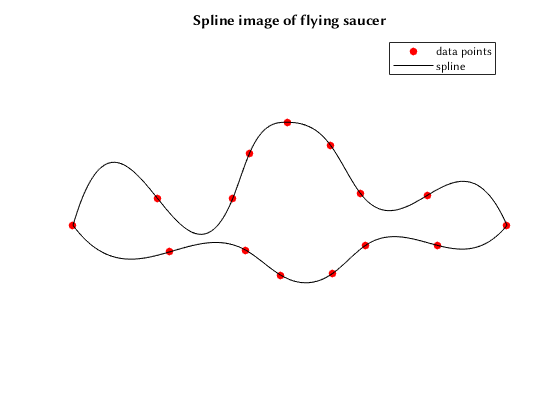

% top
xdp_t = shape_top(:,1);
ydp_t = shape_top(:,2);
x_t = linspace(xdp_t(1), xdp_t(end), 200)';
y_t = interp1(xdp_t, ydp_t, x_t, 'spline');

% bottom
xdp_b = shape_bottom(:,1);
ydp_b = shape_bottom(:,2);
x_b = linspace(xdp_b(1), xdp_b(end), 200)';
y_b = interp1(xdp_b, ydp_b, x_b, 'spline');

% plot
clf
plot([xdp_t; xdp_b], [ydp_t; ydp_b], 'r.', 'MarkerSize', 20), hold on
plot([x_t; flip(x_b)], [y_t; flip(y_b)], 'k')
axis equal, axis off
title('Spline image of flying saucer')
legend('data points', 'spline')

### Version 2.

A cleaner version using a for-loop a new type of MATLAB array called *cells*:

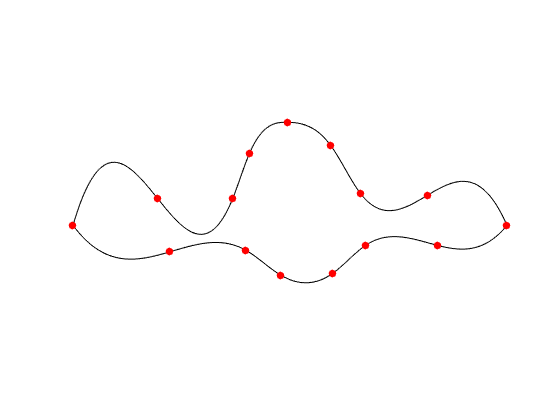

DATA{1} = shape_top;         % DATA is a cell array.
DATA{2} = shape_bottom;
clf
for i = 1:2
    xdp = DATA{i}(:,1);
    ydp = DATA{i}(:,2);
    x = linspace(xdp(1), xdp(end), 200)';
    y = interp1(xdp, ydp, x, 'spline');
    plot(x, y, 'k'), hold on
    plot(xdp, ydp, 'r.', 'MarkerSize', 20)
    hold on
end
axis equal, axis off

If you learn more about cell arrays and structures, read **LM** Section 6.3.

## Functions Used

### Newton Iteration for Systems

function x = newtonsys(f,x1)
% NEWTONSYS   Newton's method for a system of equations.
% Input:
%   f        function that computes residual and Jacobian matrix
%   x1       initial root approximation (n-vector)
% Output
%   x        array of approximations (one per column, last is best)

% Operating parameters.
    funtol = 1000*eps;  xtol = 1000*eps;  maxiter = 40;

    x = x1(:);
    [y,J] = f(x1);
    dx = Inf;
    k = 1;

    while (norm(dx) > xtol) && (norm(y) > funtol) && (k < maxiter)
        dx = -(J\y);   % Newton step
        x(:,k+1) = x(:,k) + dx;

        k = k+1;
        [y,J] = f(x(:,k));
    end

    if k==maxiter, warning('Maximum number of iterations reached.'), end
end

### Residual and Jacobian function for #5

function [f,J] = nlsystem(u)
    f = [ (1-u(4)/25)*u(1) - 5;
          (1-u(4)/16)*u(2) - 4;
          (1-u(4)/9)*u(3) - 3;
          u(1)^2/25 + u(2)^2/16 + u(3)^2/9 - 1];
    J = [ 1-u(4)/25, 0, 0, -u(1)/25;
          0, 1-u(4)/16, 0, -u(2)/16;
          0, 0, 1-u(4)/9,  -u(3)/9;
          2*u(1)/25, 2*u(2)/16, 2*u(3)/9, 0];
end
